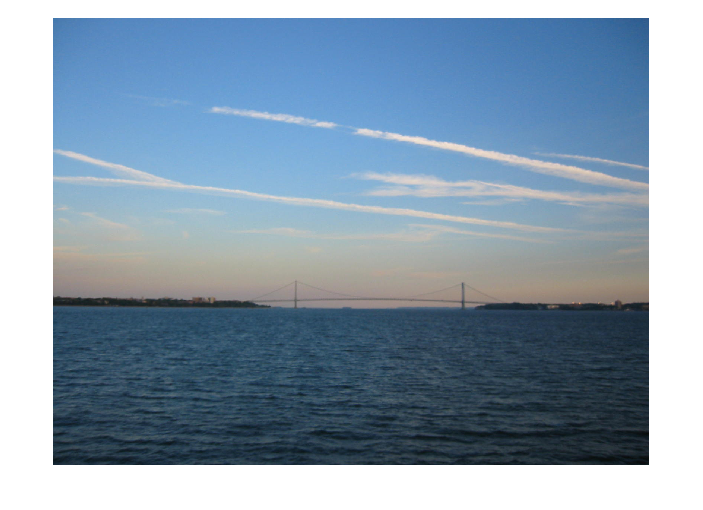

%Importeren van de afbeelding
I = imread("C:\Users\deneve.s\Documents\Defensie\KMS\2023-2024\SEM 1\ES311 - Signal Processing\verazano-day.jpg");
imshow(I)


I_height = size(I, 1);
I_width = size(I, 2);

I_maxdim = max([I_height, I_width]);

%Implementeer de impulsrespontie
H = zeros(1, 11, 3);
H(1, :, :) = ones(1,11,3)./11

H = H(:,:,1) =

    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909


H(:,:,2) =

    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909


H(:,:,3) =

    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909    0.0909




%Convolueer
A = conv2(I(:,:,1), H(:,:,1))

A =     5.9091   11.8182   17.6364   23.4545   29.0909   34.7273   40.2727   45.8182   51.5455   57.4545   63.4545   63.8182   64.1818   64.8182   65.5455   66.6364   67.7273   69.0000   70.2727   71.3636   72.2727   73.0909   73.6364   74.1818   74.5455   74.8182   74.9091   75.0000   75.0000   75.0000   75.0000   74.9091   74.7273   74.4545   74.1818   73.9091   73.7273   73.5455   73.3636   73.2727   73.0000   72.7273   72.5455   72.4545   72.4545   72.4545   72.4545   72.3636   72.6364   73.0000
    6.1818   12.3636   18.3636   24.3636   30.2727   36.1818   42.0909   48.0000   53.9091   59.9091   66.0000   66.1818   66.3636   66.9091   67.6364   68.4545   69.3636   70.2727   71.1818   72.0909   72.9091   73.6364   74.0909   74.5455   74.8182   74.9091   75.0000   75.0000   75.0000   75.0000   75.0000   75.0000   74.8182   74.6364   74.4545   74.3636   74.2727   74.1818   74.1818   74.1818   74.0909   74.0000   73.9091   74.0000   74.0909   74.1818   74.1818   74.1818   74.3636   74

imshow(round(A))



%Door zeropadding de afbeeling nxn maken, uitgaande van een afbeelding
I_resized = zeros(I_maxdim, I_maxdim, 3);
I_resized(1:I_height,1:I_width,:) = I;


%Implementeer de impulsrespontie
H_resized = zeros(I_maxdim, I_maxdim, 3);
H_resized(1:I_height,1:I_width,:) = H;

Unable to perform assignment because the size of the left side is 1200-by-1600-by-3 and the size of the
right side is 1-by-11-by-3.


H_resized = H_resized./11;

%Genereer noise
Q = wgn(I_maxdim, I_maxdim, 1);
N = zeros(I_maxdim, I_maxdim, 3);
N(:,:,1) = Q;
N(:,:,2) = Q;
N(:,:,3) = Q;

%Bereken de fft's
I_fft = fft2(I_resized);
H_fft = fft2(H_resized);
N_fft = fft2(N);

%Bereken de convolutie
G_fft = I_fft(:,:,3)*H_fft(:,:,3);

%Bereken F
F = G_fft(:,:,1)*inv(H_fft(:,:,3)); %- N_fft./H_fft;
%F = F(1:I_height, 1:I_width, :);

%IFFT
imshow(ifft2(F))